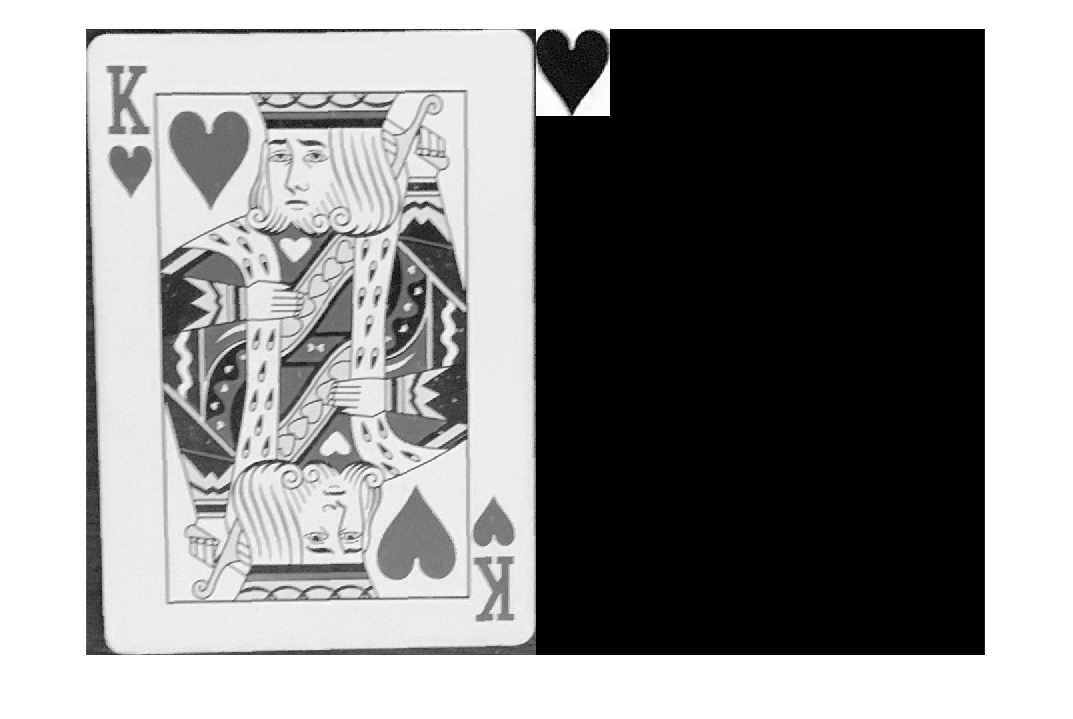

%load cropped2 
%cropped2 = rgb2gray(imread('V:\Datasets\Card Suits\Clubs\7.jpg'));
%imshowpair(R,cropped2,'montage');
template = imread("heartTemplate1.jpg");
%R = imadjust(imread('V:\Datasets\Playing Cards\SuitRankTests\First Results\CardRank43.jpg'));
imshowpair(R,template,'montage');

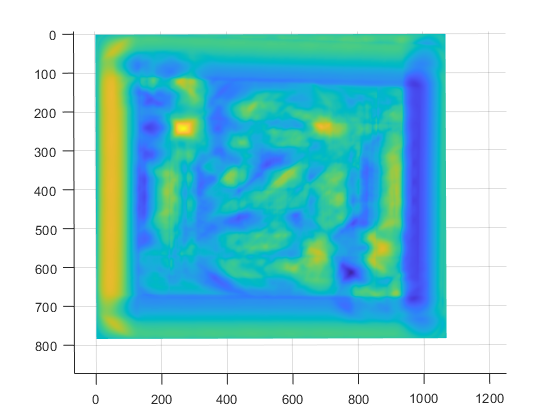

c = normxcorr2(template,imadjust(R));
figure, surf(c), shading flat

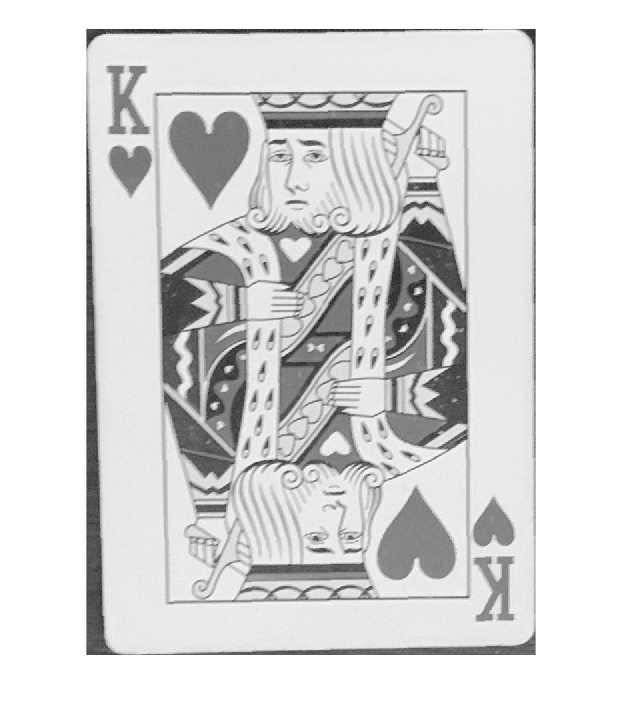

[ypeak, xpeak] = find(c==max(c(:)));
yoffSet = ypeak-size(R,2);
xoffSet = xpeak-size(R,1);
figure
imshow(R);
imrect(gca, [xoffSet+1, yoffSet+1, size(R,2), size(R,1)]);